global rpm2rad deg2rad
rpm2rad = 2*pi/60;
deg2rad = pi / 180;
rpm = 10000;
dt = 0.00001;


%=============1st measurement============

%define inital unknown imbalance
unknown_mass = 0.000001;
unknown_mass_anlge = 30;

%simulate
offset_masses = [unknown_mass unknown_mass_anlge*deg2rad];
[amp1, phase1] = simulate_vibration(offset_masses, rpm*rpm2rad, 100*60/rpm , dt)

amp1 = 0.3290

phase1 = 30.0001


%plot
clf
polarplot([0 phase1*deg2rad], [0 amp1])

%=============2nd measurement============

%define test mass
test_mass = 0.000002;
test_angle = 150;

%simulate
offset_masses = [unknown_mass unknown_mass_anlge*deg2rad; test_mass test_angle*deg2rad];
[amp2, phase2] = simulate_vibration(offset_masses, rpm*rpm2rad, 100*60/rpm , dt);

%plot
hold on
polarplot([0 phase2*deg2rad], [0 amp2])


%=============calculate correction mass==
T_amp = sqrt(amp1^2 + amp2^2 - (2*amp1*amp2*cosd(phase2-phase1)));
theta = asind(amp2 * (sind(phase2-phase1) / T_amp));
if theta < 0
     theta = -1*(180+theta)
 end
theta

theta = 59.9993

cor_mass = test_mass * (amp1 / T_amp);
cor_angle = test_angle + theta;

%=============3rd measurement============

%simulate
offset_masses = [unknown_mass unknown_mass_anlge*deg2rad; cor_mass cor_angle*deg2rad];
[amp3, phase3] = simulate_vibration(offset_masses, rpm*rpm2rad, 100*60/rpm , dt)

amp3 = 5.9139e-06

phase3 = 164.4406

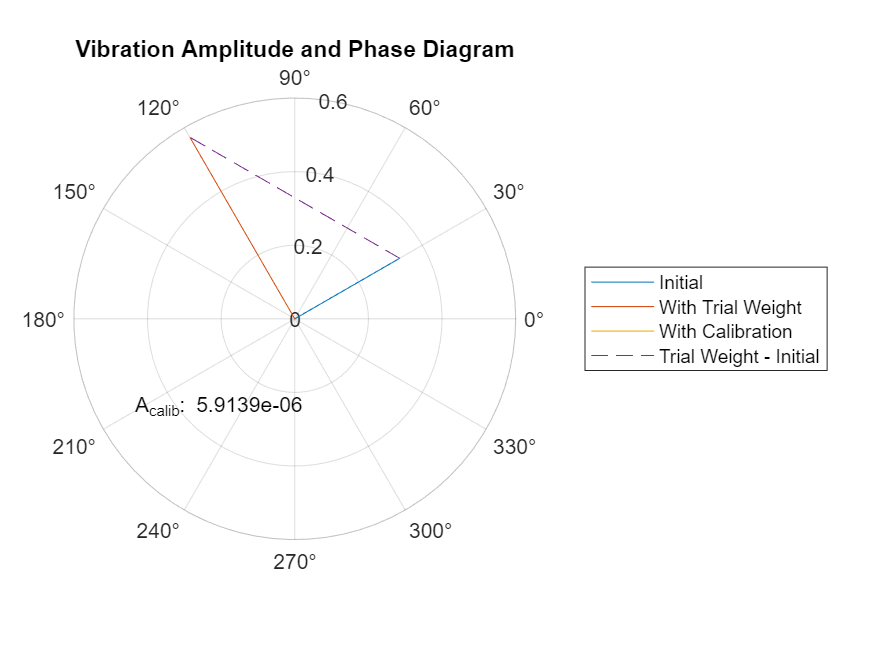


%plot
polarplot([0 phase3*deg2rad], [0 amp3])

%plot other bits and bobs
polarplot([phase1*deg2rad phase2*deg2rad], [amp1 amp2], '--')
legend("Initial", "With Trial Weight", "With Calibration", "Trial Weight - Initial")
title("Vibration Amplitude and Phase Diagram")
txt = 'A_{calib}: ' + string(amp3);
text(0.5,-0.5,txt)

speed = 50;
animate_wheel(fw_a_data, speed, offset_masses);

%animate_rocker(r_a_data, speed);

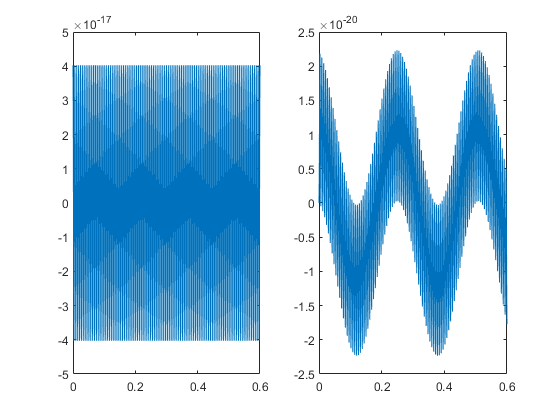

figure(1)
clf
subplot(1,2,1)
plot(fw_data(:,1), fw_data(:,3))

subplot(1,2,2)
plot(r_data(:,1), r_data(:,2))

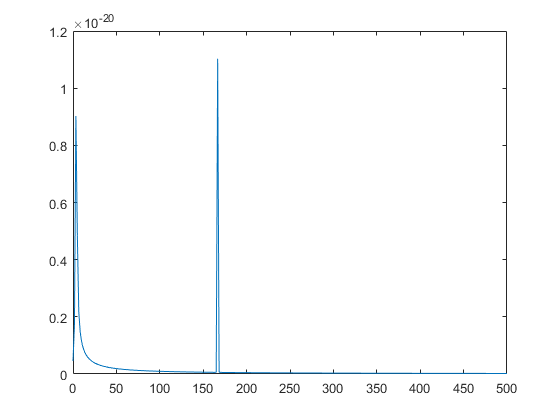


figure(3)
clf
Y = fft(r_data(:,2));
Fs = 1/dt;
T = 1/Fs;
L = length(r_data(:,1))-1;

P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;
plot(f, P1)
xlim([0,500])


[val, id] = max(P1(100:500));
fft_rpm = f(id+99) * 60;
disp(string(fft_rpm) + ' rpm')

10000 rpm


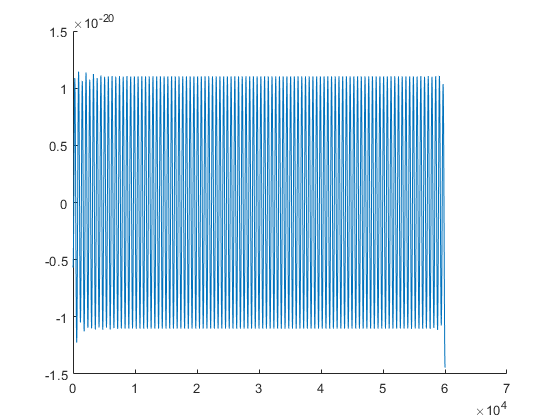


figure()
clf
d = r_data(:,2);
fd = highpass(d, 100, 1/dt);
%plot(d)
hold on
plot(fd)

rot = cos(fw_data(:,2));
[c, lag] = xcorr(rot, fd);
[val, id] = max(c);
lag = lag(id);
phase = (lag) * dt * rpm * rpm2rad * 180/pi

phase = -179.4000

t = linspace(0,100*pi,100000);
dt = t(2) - t(1);
d1 = sin(t + (0 * pi / 180));
d2 = sin(t + (355 * pi / 180));


phdiffmeasure(d1, d2) * 180 / pi

ans = -5.0000


% figure(1)
% clf
% plot(t, d1)
% hold on
% plot(t, d2)
% hold off




    [c, lag] = xcorr(d1, d2);

    figure(2)
% clf
% hold on
% plot(c)
% plot(lag)
% hold off
    [val, id] = max(c);
    lag = lag(id);
    phase = round((lag) * dt * 180 / pi)

phase = -5

    
    
  finddelay(d1,d2)

ans = 28


global rpm2rad deg2rad
rpm2rad = 2*pi/60;
deg2rad = pi / 180;
rpm = 10000;
dt = 0.00001;

%simulate
offset_masses = [0.000001, 90*deg2rad ;
                 0.000001, 10*deg2rad];

[fw_data, fw_a_data] = fly_wheel(offset_masses, rpm*rpm2rad, 50 * 60/rpm, dt);
[r_data, r_a_data] = rocker(fw_data);

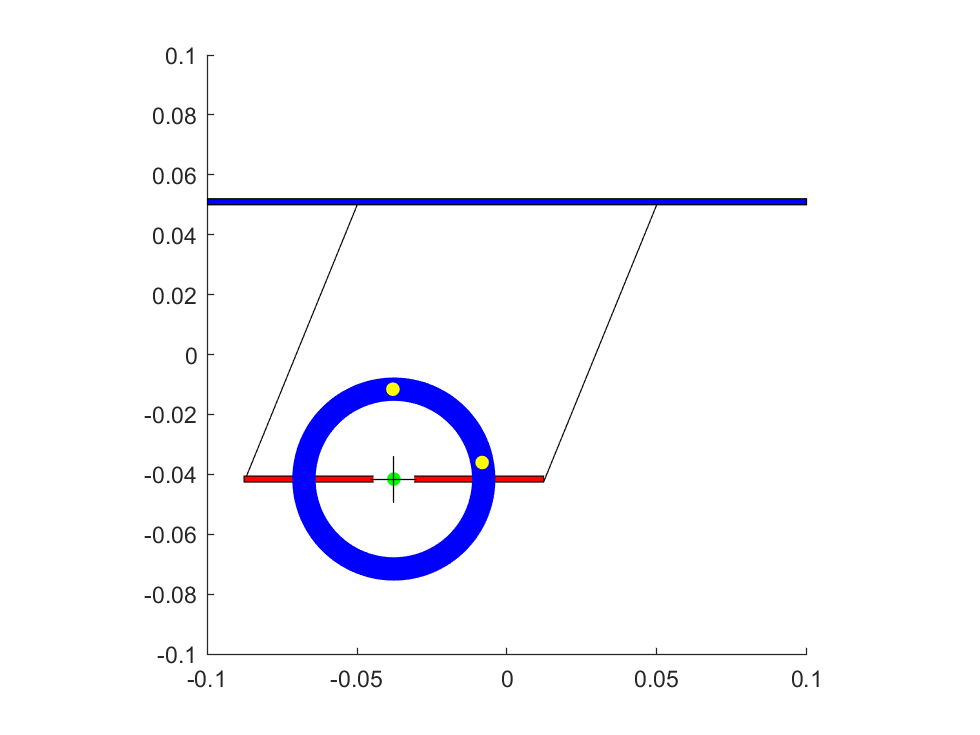

ans = 1


speed = 100;

animate_sys(fw_a_data, r_a_data, offset_masses, speed)